2

株価データ読み込み　外れ値の含むものを削除

cd(rootdir)
cd("vars")
load('Co_infoTbl_1','Co_infoTbl')
cd(rootdir)
priceFiles=dir("output\stockData\*.csv");
priceFiles=priceFiles([priceFiles.bytes]>1000);

欠損値または外れ値がpermitNanNumより多いデータは使わない

permitNanNum=20;
for i=1:length(priceFiles)
    tmpPriceTbl=readtable(fullfile(priceFiles(i).folder,priceFiles(i).name),"Encoding","UTF-8");

外れ値の削除

    [~,j]=hampel(table2array(tmpPriceTbl(:,{'high','low','open','close','volume'})),4,30);
    if nnz(j)<=permitNanNum
        tmpPriceTbl=rmoutliers(tmpPriceTbl,"movmean",2,"DataVariables",{'high','low','open','close'},"ThresholdFactor",10);
        tmpPriceTbl=fillmissing(tmpPriceTbl,"movmean",2,'DataVariables',{'high','low','open','close','volume'});
        tmpPriceTbl=fillmissing(tmpPriceTbl,"nearest",'DataVariables',{'high','low','open','close','volume'});
        tmpPriceTbl=table2timetable(tmpPriceTbl(:,["timestamp","high","low","open","close","volume","code"]));
        Co_infoTbl(Co_infoTbl.code==tmpPriceTbl.code(1),"priceTimeTbl")={sortrows(tmpPriceTbl,"timestamp","descend")};
    end
end

Co_infoTbl.existPriceTimeTbl=arrayfun(@(tt) istimetable(tt{1}),Co_infoTbl.priceTimeTbl);
clear tmpPriceTbl priceFiles permitNanNum
cd("vars")
save Co_infoTbl_2 Co_infoTbl

cd(rootdir)
cd("vars")
load("cleanVocaTbl_1","cleanVocaTbl")
load("vocaTbl_1.mat","vocaTbl")
cd(rootdir)
interestFiles=dir("output\interestOverTime\*.csv");
interestFiles=interestFiles([interestFiles.bytes]>1000);
tmptbl=[];
maxNumOf0=50;
numOf0=[];
cnt=0;

for i=1:length(interestFiles)
    tmptbl=readtable(fullfile(interestFiles(i).folder,interestFiles(i).name),"Encoding","UTF-8","PreserveVariableNames",true,"ReadVariableNames",true);
    tmptbl.Properties.VariableNames{2}='value';
    numOf0(i)=nnz(tmptbl.value==0);
    if numOf0(i)<maxNumOf0
        tmptbl{tmptbl.value==0,"value"}=nan;
        tmptbl=fillmissing(tmptbl,"movmean",2,"DataVariables","value");
        tmptbl=fillmissing(tmptbl,"nearest","DataVariables","value");
        cleanVocaTbl(tmptbl.wordIdx(1),"interestTimeTbl")={sortrows(table2timetable(tmptbl(:,["date","value"])),"date","descend")};
        cnt=cnt+1;
    end
end

cnt

cnt = 4305

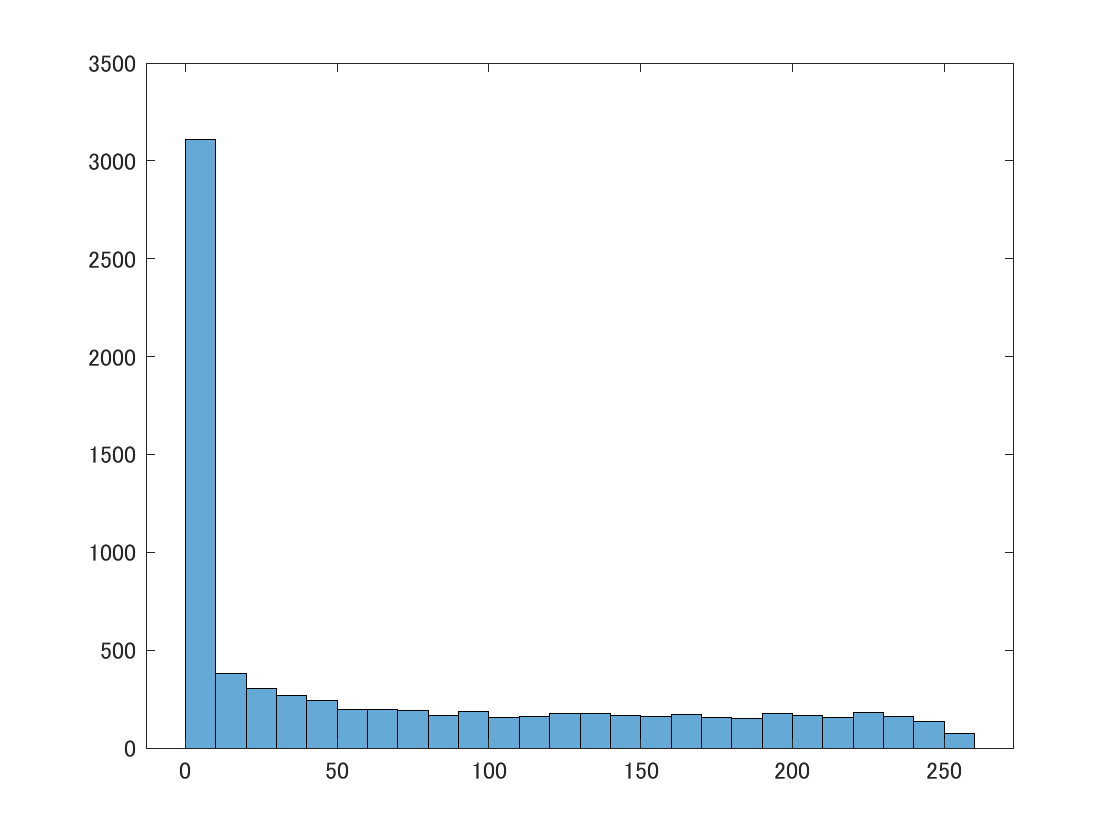

figure
histogram(numOf0)

for i=1:height(cleanVocaTbl)
    if istimetable(cleanVocaTbl.interestTimeTbl{i})
        vocaTbl.interestTimeTbl(cleanVocaTbl.preIdx(i))=cleanVocaTbl.interestTimeTbl(i);
        vocaTbl.existInterest(cleanVocaTbl.preIdx(i))=true;
    end
end

clear tmptbl cnt interestFiles maxNumOf0 numOf0 cleanVocaTbl

cd("vars")
save vocaTbl_2 vocaTbl